# Filter Design

## Signal Analysis

### 1. Load Source Data

The First step we need to do is load the source data.

signal_data = readtable("data/Data.csv");
signal_data.Properties.VariableNames = {'voltage'}

signal_data = 5000×1 table
      voltage  
    ___________

     -0.0071204
      -0.037849
      0.0098115
       0.014035
     -0.0058711
      -0.011737
      -0.024535
       0.060389
       0.032185
      0.0019119
    -0.00030942
      -0.026549
      -0.010176
       -0.01959
      -0.026645
       0.015229


The data points are in mV, so in order to design our filter correctly we need to put them in V.

signal_data.voltage = signal_data.voltage * 1e-3

signal_data = 5000×1 table
      voltage  
    ___________

    -7.1204e-06
    -3.7849e-05
     9.8115e-06
     1.4035e-05
    -5.8711e-06
    -1.1737e-05
    -2.4535e-05
     6.0389e-05
     3.2185e-05
     1.9119e-06
    -3.0942e-07
    -2.6549e-05
    -1.0176e-05
     -1.959e-05
    -2.6645e-05
     1.5229e-05


### 2. Analise de Freq.

fs = 100;  % Sampling Frequency
dt = 1/fs; % Time interval between measurements

N = 0.1 * fs; % Total Number of points
M = 2^(nextpow2(N));             % The largest number that is a power of two and less than the number of points

df = 1/(M*dt);          % Frequency step
f  = [0:df:(M-1)*df];   % Frequency domain, from 0
%w  = hann(N);

Y  = fft(w .* signal_data.voltage, M); % Fast Fourier
mY = abs(Y);                      % Magnitude
Pyy= (Y .* conj(Y));              % Power


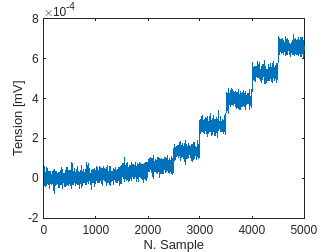

hold off; clear figure
plot(signal_data.voltage);
xlabel('N. Sample'), ylabel('Tension [mV]')

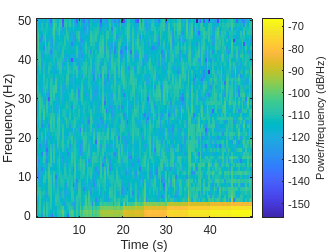

spectrogram(signal_data.voltage, 50, 10,100,fs, 'yaxis')

a = filter(e_filter, signal_data.voltage)

a = 1.0e-03 *

   -0.0000
   -0.0003
   -0.0010
   -0.0015
   -0.0017
   -0.0019
   -0.0023
   -0.0025
   -0.0020
   -0.0009


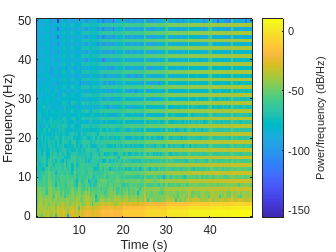

a = a * 7e3;
clf
spectrogram(a, 50, 10,100,fs, 'yaxis')

max(a(2550:3000)) - mean(a(2550:3000))

ans = 0.0550

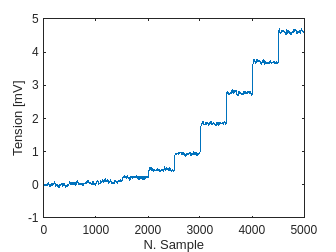

plot(a)
xlabel('N. Sample'), ylabel('Tension [mV]')

R = 500 % resistencia em ohms

R = 500

GF = 2.2 % gauge Factor

GF = 2.2000

Ei = 12 % Tensão iniciam em V

Ei = 12

f = 100 % freq da taxa em hz

f = 100

clf
epsilon = (4*a*1e-3)/(GF*Ei); %é a deformação
potato = fit(a, epsilon, 'poly1')

potato =      Linear model Poly1:
     potato(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =   0.0001515  (0.0001515, 0.0001515)
       p2 =    9.38e-21  (-2.03e-22, 1.896e-20)

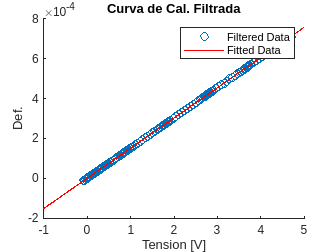

hold on;
scatter(a, epsilon);
plot(potato);
xlabel('Tension [V]'), ylabel('Def.');
legend('Filtered Data', 'Fitted Data')
title('Curva de Cal. Filtrada')